P = imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena256.bmp");
P = Imreadforgary(P);
C =  imread("C:\Users\Liushoukang\Desktop\VMIE\image\art256.bmp");
C = Imreadforgary(C);

[CICS,DI,RI]=VMIE(P,C);

历时 0.201808 秒。
历时 1.391022 秒。


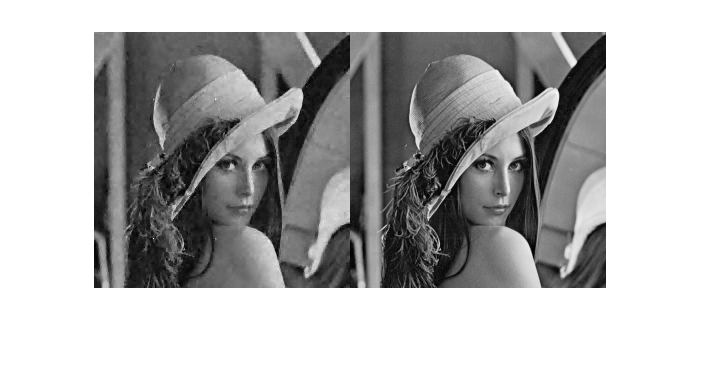

% 恢复质量测试
imshowpair(uint8(RI),uint8(P),'montage')

entropy(uint8(P))

ans = 7.5683

entropy(uint8(RI))

ans = 7.5589

entropy(uint8(DI))

ans = 7.9878

entropy()

NC(P,RI)

ans = 0.9969

psnr(uint8(RI),uint8(P))

ans = 29.2878

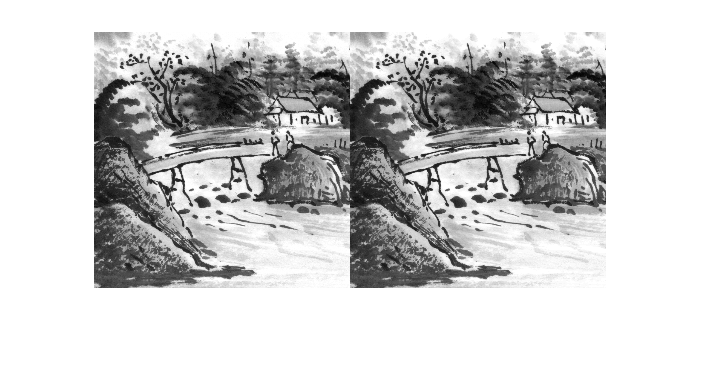

% 视觉安全测试
imshowpair(uint8(CICS),uint8(C),'montage')

entropy(uint8(C))

ans = 6.7830

entropy(uint8(CICS))

ans = 7.4534

NC(C,CICS)

ans = 1.0000

psnr(uint8(CICS),uint8(C))

ans = 45.4900